## Connect to Twitter and Import Data Via Twitter Search API v1

The variable `statuses` contains the raw data in the form a cell array where each cell a `struct` containing tweet info

clear; clc; 

% Build query and parameters
query = 'hedera OR hbar OR hashgraph -filter:retweets';
parameters.count = 100;
parameters.lang = 'en';
parameters.tweet_mode = 'extended';
getAllTweets = false;

% 
% load statuses100Dec23.mat;
load statusesDec23.mat;
% statuses = twitterConnectNImport_Fcn(query, parameters, getAllTweets);

## Extract Tweet Information

For each tweet, this section extracts: 

- Creation time (string)

- Text (string)

- Author handle (string)

- Author name (string)

- Mentions included (cell array containing string arrays)

- Hashtags used (cell array containing string arrays)

These variables are then combined in table variables sorted by different criteria.

% Extract all tweets sorted by time, # of likes,and # of RTs
[tableTweetsSortedByTime, ...
    tableTweetsSortedByLikes, ...
    tableTweetsSortedByRetweets] = ExtractTweetTextNInfo_Fcn(statuses);

numTweetsTotal = height(tableTweetsSortedByTime);

## Identify & Sort: Most Active Users, Most Mentioned Users, and Most Used Hashgtags

% % Identify the most active user handles
tableTweetsPerAuthor = identifyCommonString_Fcn(tableTweetsSortedByTime.tweetAuthorHandle);
tableTweetsPerAuthor = includeTweetsBy_Fcn(tableTweetsPerAuthor, tableTweetsSortedByTime, "tweetAuthorHandle");
tableTweetsPerAuthor = sortTblAlph_Fcn(tableTweetsPerAuthor);

% Identify the most mentioned users
tableTweetsPerMention = identifyCommonString_Fcn(tableTweetsSortedByTime.tweetUniqueMentions);
tableTweetsPerMention = includeTweetsBy_Fcn(tableTweetsPerMention, tableTweetsSortedByTime, "tweetUniqueMentions");
tableTweetsPerMention = sortTblAlph_Fcn(tableTweetsPerMention);

% Identify the most used hashtags
tableTweetsPerHashtag = identifyCommonString_Fcn(tableTweetsSortedByTime.tweetUniqueHashtags);
tableTweetsPerHashtag = includeTweetsBy_Fcn(tableTweetsPerHashtag, tableTweetsSortedByTime, "tweetUniqueHashtags");
tableTweetsPerHashtag = simplifyHashtagTable_Fcn(tableTweetsPerHashtag);

## Generate Twitter Activity Reports - Filtered & Sorted

tblNames = [...
    "tableTweetsPerAuthor", ...
    "tableTweetsPerMention", ...
    "tableTweetsPerHashtag" ...
    ];

tblData = {...
    tableTweetsPerAuthor, ...
    tableTweetsPerMention, ...
    tableTweetsPerHashtag ...
    };

% Generate reports for filtered tweets (PerAuthor, PerMention, PerHashtag)
for idxRpt = numel(tblNames): -1: 1
rptPerXXX(idxRpt) = generateReportsPer_Fcn(tblNames(idxRpt), tblData{idxRpt}, true, numTweetsTotal);
end 

Generating report for... tableTweetsPerHashtag
Generating wordcloud...
Done
 
Generating report for... tableTweetsPerMention
Generating wordcloud...
Done
 
Generating report for... tableTweetsPerAuthor
Generating wordcloud...
Done
 


% Generate report for sorted tweets (byTime, byLikes, byRTs
rptSorted = generateReportSorted_Fcn(tableTweetsSortedByTime, tableTweetsSortedByLikes, tableTweetsSortedByRetweets, numTweetsTotal);

Generating report for sorted tweets...
Done


## Pre-Process Text Data

[cleanDocuments, rawDocuments] = preprocessTextFcn(tableTweetsSortedByTime.tweetTexts);

hashtags2rem = "#" + tableTweetsPerHashtag.labels;
mentions2rem = "@" + unique([tableTweetsPerAuthor.labels ; tableTweetsPerMention.labels]);
words2remove = [hashtags2rem; mentions2rem];

cleanDocuments = removeWords(cleanDocuments, words2remove, "IgnoreCase", true);

## Compare raw and clean data

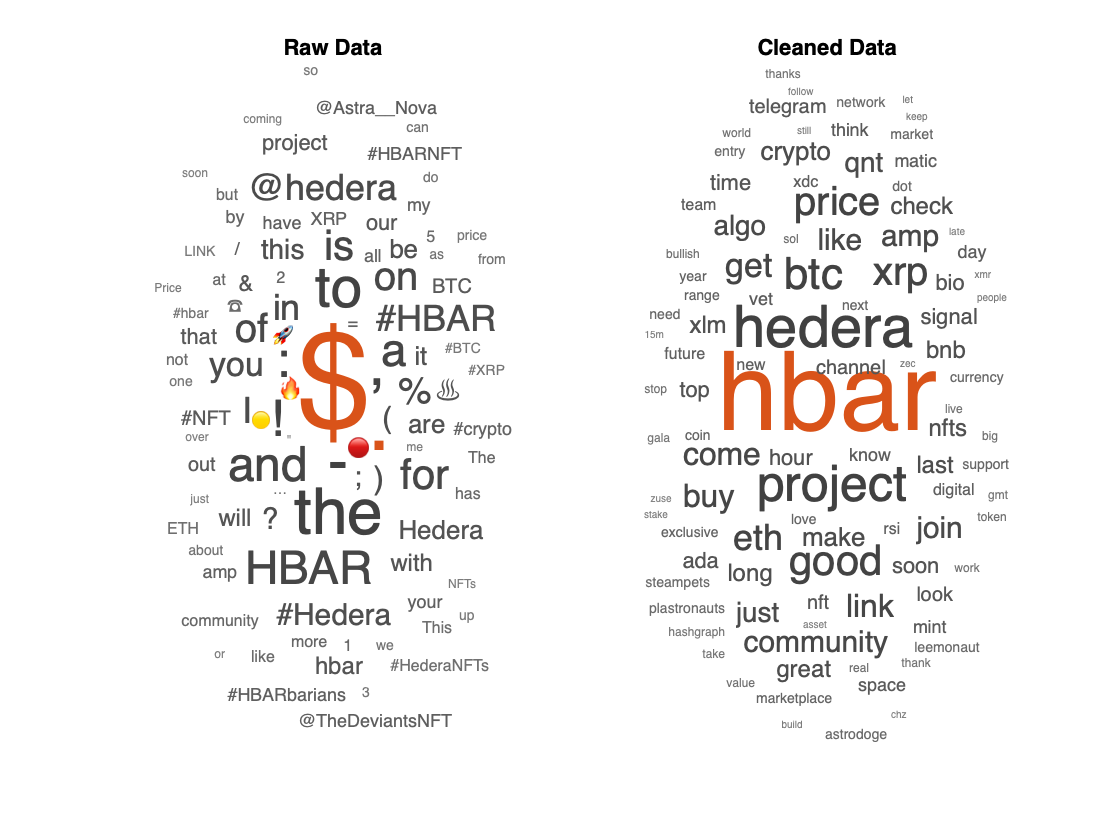

[cleanedBag, rawBag, reduction] = compareRawNCleanFcn(cleanDocuments,rawDocuments);

## **Conduct Sentiment Analysis on Tweets**

Create a glossary of words that are associated with positive sentiment. `poskeywords `is a cell array of character vectors. Each character vector is a word that represents an instance of positive sentiment.

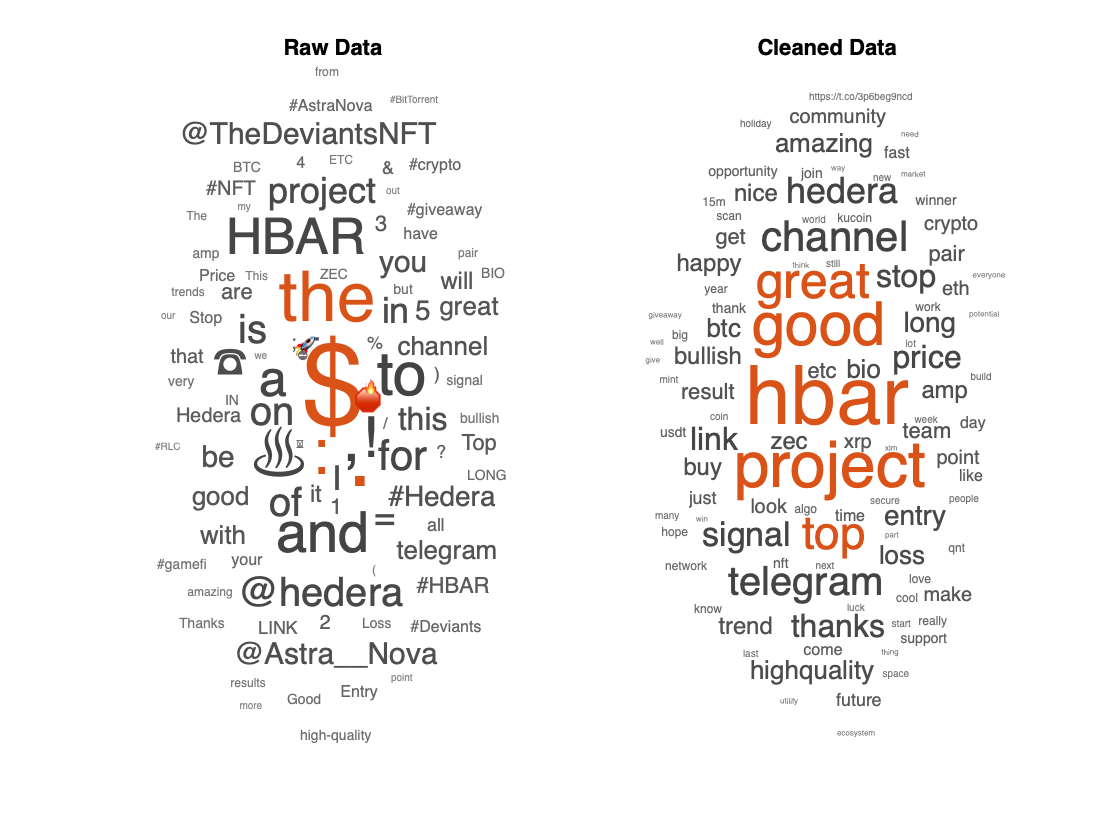

poskeywords = {'happy','great','good', ...
    'fast','optimized','nice','interesting','amazing','top','award', ...
    'winner','wins','cool','thanks','useful','secure','fast','abft','decentralized',...
    'positive', 'solid', 'scalable', 'low cost' };

[numPosTweets , posTweetsText]= sentimentAnalysisFcn(tableTweetsSortedByTime.tweetTexts, poskeywords);
[aa,bb] = preprocessTextFcn(posTweetsText);
aa = removeWords(aa, words2remove, "IgnoreCase", true);
[cleaned, raw, redx] = compareRawNCleanFcn(aa,bb);

Create a glossary of words that are associated with negative sentiment. `negkeywords` is a cell array of character vectors. Each character vector is a word that represents an instance of negative sentiment.

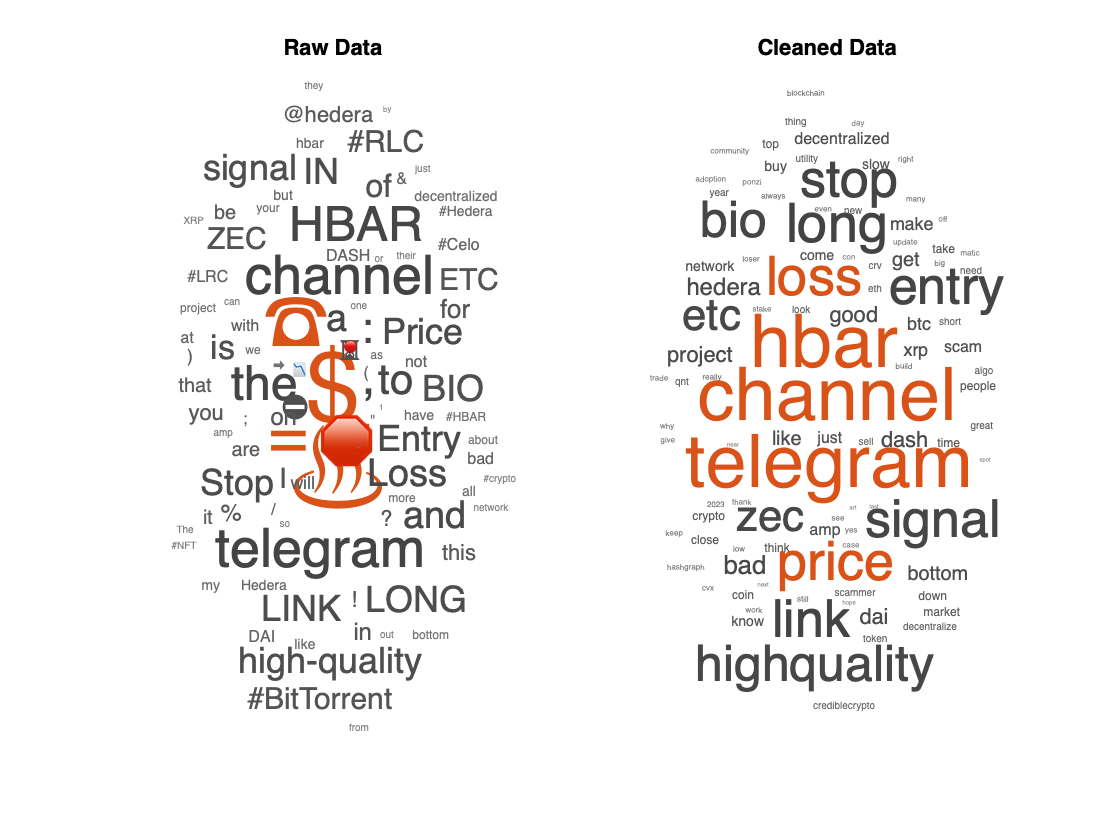

negkeywords = {'sad','poor','bad','slow','weak','boring', ...
    'bottom','loss','loser','loses','uncool', ...
    'useless','centralized','garbage', 'scam', 'terrible'};

[numNegTweets , negTweetsText]= sentimentAnalysisFcn(tableTweetsSortedByTime.tweetTexts, negkeywords);
[aaa, bbb] = preprocessTextFcn(negTweetsText);
aaa = removeWords(aaa, words2remove, "IgnoreCase", true);
[cleaned1, raw1, redx1] = compareRawNCleanFcn(aaa, bbb);

## **Display Sentiment Analysis Results**

matlabTweetTable = table(length(statuses),numPosTweets,numNegTweets, ...
    'VariableNames',{'Number_of_Tweets','Positive_Tweets', ...
    'Negative_Tweets'})

matlabTweetTable = 1×3 table
    Number_of_Tweets    Positive_Tweets    Negative_Tweets
    ________________    _______________    _______________

         13566               3024                615      
